# Runge-Kutta Example

## Predator Prey model

## Example 1

[https://www.youtube.com/watch?v=0LzDiScAcJI](https://www.youtube.com/watch?v=0LzDiScAcJI)

% Runge-Kutta method to solve predator-prey problem
% dR/dt = aR-bRF % Rabbit
% dF/dt = -lF + kRF % Fox
clear; clc;

% Constants
a = 10;
b = 1;
l = 0.1;
k = 1;

% Define function handles
fR = @(t,R,F) a*R-b*R*F;
fF = @(t,R,F) -l*F+k*R*F;

% Initial conditions
t(1) = 0;
R(1) = 20;
F(1) = 5;

% Step size
h = 0.001;
tfinal = 500;
N = ceil(tfinal/h);

% Update loop
for i = 1:N
    % Update time
    t(i+1) = t(i)+h;
    % Update R & F
    k1R = fR(t(i)    , R(i)       , F(i)       );
    k1F = fF(t(i)    , R(i)       , F(i)       );
    k2R = fR(t(i)+h/2,R(i)+h/2*k1R,F(i)+h/2*k1F);
    k2F = fF(t(i)+h/2,R(i)+h/2*k1R,F(i)+h/2*k1F);
    k3R = fR(t(i)+h/2,R(i)+h/2*k2R,F(i)+h/2*k2F);
    k3F = fF(t(i)+h/2,R(i)+h/2*k2R,F(i)+h/2*k2F);
    k4R = fR(t(i)+h  ,R(i)+h  *k3R,F(i)+h  *k3F);
    k4F = fF(t(i)+h  ,R(i)+h  *k3R,F(i)+h  *k3F);
    R(i+1) = R(i)+h/6*(k1R + 2*k2R + 2*k3R + k4R);
    F(i+1) = F(i)+h/6*(k1F + 2*k2F + 2*k3F + k4F);
end

% Plot the solution
figure(1); clf(1);
plot(t,R)
hold on
plot (t,F)
xlabel('Time')
ylabel('Populations')
legend('Rabbits', 'Foxes')
set(gca, 'Fontsize', 16)


## Example 2

[https://www.youtube.com/watch?v=172Vj3ZH2l4](https://www.youtube.com/watch?v=172Vj3ZH2l4)

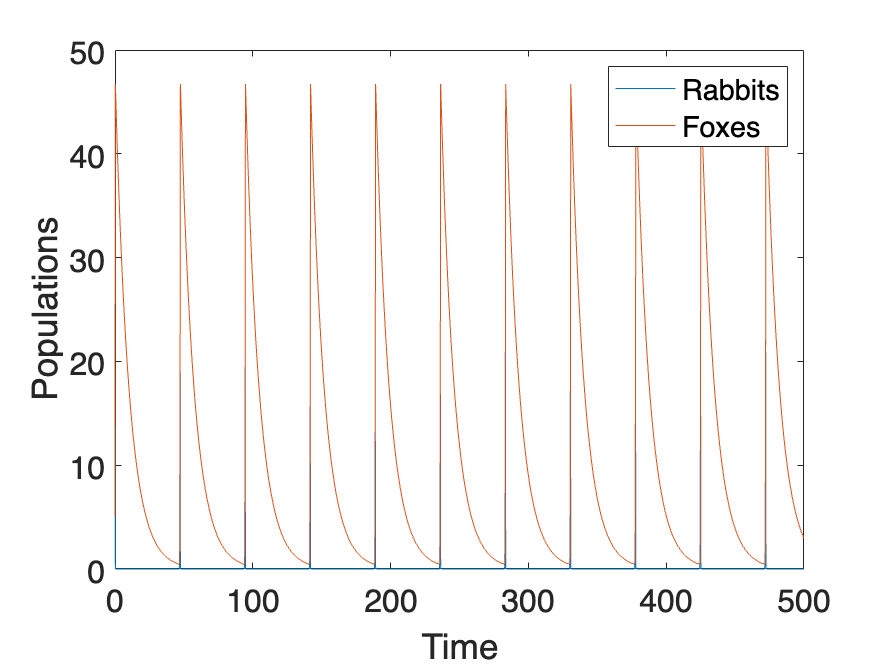

% Example 2 - Revisions
% Runge-Kutta method to solve predator-prey problem
% dR/dt = aR-bRF % Rabbit
% dF/dt = -lF + kRF % Fox
clear; clc;

% Constants
a = 10;
b = 1;
l = 0.1;
k = 1;

% Define function handles
% y=[R,F] <= y(1,:)=R y(2,:)=F
f=@(t,y) [...
    +a*y(1)-b*y(1).*y(2);
    -l*y(2)+k*y(1).*y(2)];

% Initial conditions
t(1) = 0;
y(:,1) = [20,5];

% Step size
h = 0.001;
tfinal = 500;
N = ceil(tfinal/h);

% Update loop
for i = 1:N
    % Update time
    t(i+1) = t(i)+h;
    % Update for y
    k1 = f(t(i)    ,y(:,i)       );
    k2 = f(t(i)+h/2,y(:,i)+h/2*k1);
    k3 = f(t(i)+h/2,y(:,i)+h/2*k2);
    k4 = f(t(i)+h  ,y(:,i)+h  *k3);
    y(:,i+1)=y(:,i)+h/6*(k1 + 2*k2 + 2*k3 + k4);
end

% Plot the solution
figure(1); clf(1);
plot(t,y(1,:))
hold on
plot (t,y(2,:))
xlabel('Time')
ylabel('Populations')
legend('Rabbits', 'Foxes')
set(gca, 'Fontsize', 16)